maskRegionsEllipseFit

Shuai Yang 2021.07.15

% close all
mask = mask1 ;
L = bwlabel(mask);
s = regionprops(mask, ...
    'MajorAxisLength','MinorAxisLength', ...
    'Orientation','PixelIdxList','Centroid','Area');
mask_ell = false(size(mask));
s_Ells = struct([]);
tic;
for iCell = 1:numel(s)
    each_Cell =  false(size(mask));
    each_Cell(s(iCell).PixelIdxList) = true;
    
    each_Ell = false(size(mask));% each cell ellipse
    
    angle = s(iCell).Orientation; % 角度
    angle = angle/180*pi;
    r = 0:0.01:2*pi; % 转一圈
    
    a = s(iCell).MajorAxisLength/2;%semi_MajorAxis
    b = s(iCell).MinorAxisLength/2;%semi_minorAxis
    p = [(a*cos(r))' (b*sin(r))']; % 未旋转
    alpha = [cos(angle) -sin(angle)
        sin(angle) cos(angle)];
    p1 = p*alpha; % 旋转后
    p1(:,1) =  p1(:,1) + s(iCell).Centroid(1);
    p1(:,2) =  p1(:,2) + s(iCell).Centroid(2);
    xIdx = round(p1(:,1));
    yIdx = round(p1(:,2));
%     [X,Y] = meshgrid(xIdx,yIdx);
%     ind = sub2ind([2048,2048],Y(:),X(:));
    ind = sub2ind([2048,2048],yIdx(:),xIdx(:));
    
    each_Ell(ind) = true;    
    each_EllMask = imfill(each_Ell,'holes');
    
    s_Ell = regionprops(each_EllMask, 'Area');
    
    s_Ells(iCell).Area = s_Ell.Area;
%     s_Ells(iCell).Perimeter = s_Ell.Perimeter;
    
    ellIn = and(each_EllMask,each_Cell);    
    %椭圆内cell region 面积占比
    ellOut = and(~each_EllMask,each_Cell);  
    %椭圆外cell region面积占比
    s_Ells(iCell).ellInPixels = sum(ellIn(:));
    s_Ells(iCell).ellOutPixels = sum(ellOut(:));
    
%     s(iCell).ellPerimeter = s_Ell.Perimeter;
    s(iCell).ellArea = s_Ell.Area;
    s(iCell).ellInPixels = sum(ellIn(:));
    s(iCell).ellOutPixels = sum(ellOut(:));
    s(iCell).ellInPixelsProportion = s(iCell).ellInPixels/s(iCell).ellArea;
    
    mask_ell = or(mask_ell,each_Ell);
    
end
toc;

历时 39.509690 秒。


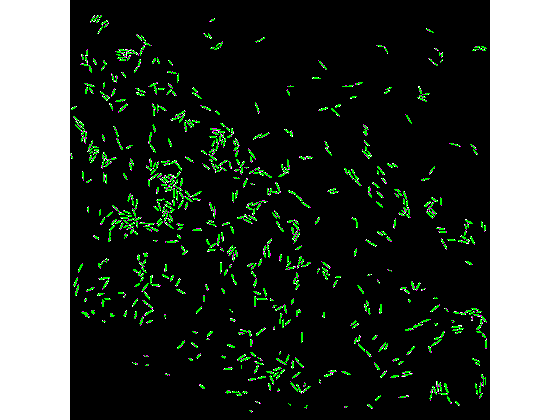

figure,imshowpair(mask,mask_ell)

% ell = patch(p1(:,1),p1(:,2),[255 225 225]/255,'EdgeColor',[1 0 0]);

 fwrong = find([s.ellInPixelsProportion] < 0.7);
 wrongbw = ismember(L, fwrong);
 goodones = setdiff(1:max(max(L)), fwrong);
goodbw = ismember(L, goodones);%没有fwrong剩下的bw图像